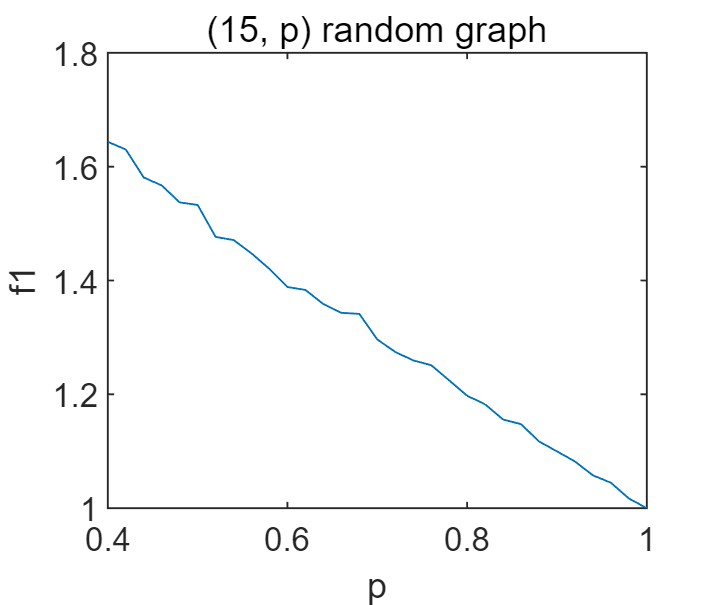

% Calculate and plot the expected values of f1, f2, f3 and fw for a (N, p) random graph
% N: 15 vertices (graph of fixed size)
% p: Take the probabilities in the range of 0 - 1 with an interval of 0.02, so p values are 50 in total
% For each value of p, calculate f1, f2, f3 and fw under the current p using the average of 50 samples  
% horizontal coordinates: p values
% vertical coordinates: f1/f2/f3/fw

% Record the f1, f2, f3, fw and p values (50 in total) 
avgPathLenRecord = zeros(1, 50);
diameterRecord = zeros(1, 50);
linkNumRecord = zeros(1, 50);
fwRecord = zeros(1, 50);
pRecord = zeros(1, 50);

size = 50;
N = 15;

% Calculate 50 values of f1 corresponding to 50 probabilities and plot them
p = 0;
for count = 1 : 50
    p = p + 0.02;
    pRecord(count) = p;
    % Generate 50 (N,p) random graphs, calculate the average as the
    % objective function's value under current p
    randomGraphs = gen_N_p_random_graphs(size, N, p);
    temp = zeros(1, size);
    for index = 1 : size
        temp(index) = cal_avg_path_len(randomGraphs{index});
    end
    avgPathLenRecord(count) = mean(temp);
end

set(gcf,'Position',[100 100 260 220]);
plot(pRecord, avgPathLenRecord);
xlabel("p")
ylabel("f1")
title("(" + N + ", p)" + " random graph");

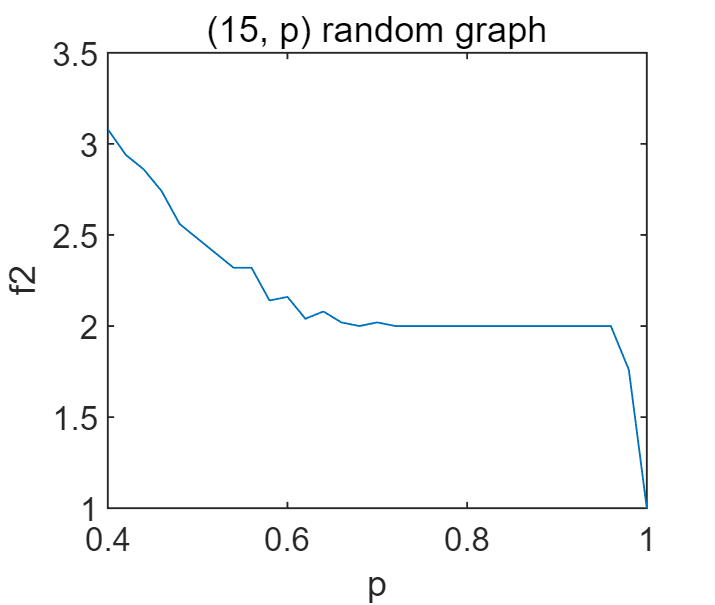

% Calculate 50 values of f2 corresponding to 50 probabilities and plot them
p = 0;
for count = 1 : 50
    p = p + 0.02;
    pRecord(count) = p;
    randomGraphs = gen_N_p_random_graphs(size, N, p);
    temp = zeros(1, size);
    for index = 1 : size
        temp(index) = cal_diameter(randomGraphs{index});
    end
    diameterRecord(count) = mean(temp);
end

plot(pRecord, diameterRecord);
xlabel("p")
ylabel("f2")
title("(" + N + ", p)" + " random graph");

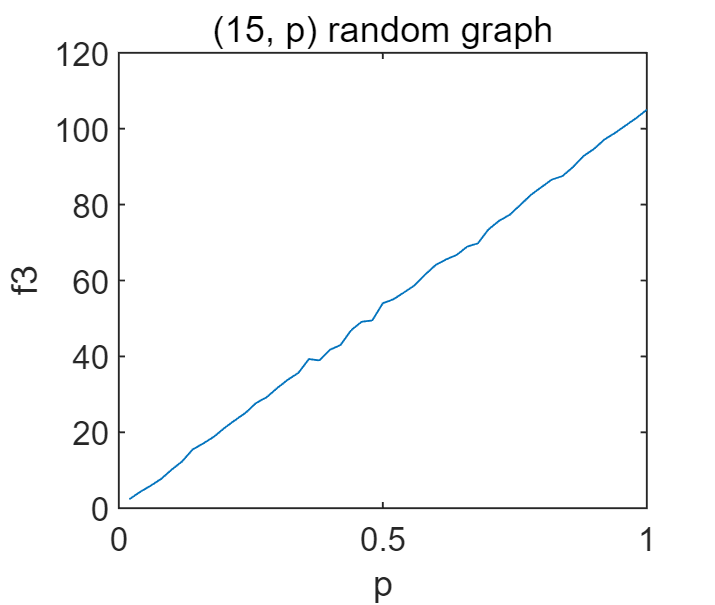

% Calculate 50 values of f3 corresponding to 50 probabilities and plot them
p = 0;
for count = 1 : 50
    p = p + 0.02;
    pRecord(count) = p;
    randomGraphs = gen_N_p_random_graphs(size, N, p);
    temp = zeros(1, size);
    for index = 1 : size
        temp(index) = cal_link_num(randomGraphs{index});
    end
    linkNumRecord(count) = mean(temp);
end

plot(pRecord, linkNumRecord);
xlabel("p")
ylabel("f3")
title("(" + N + ", p)" + " random graph");

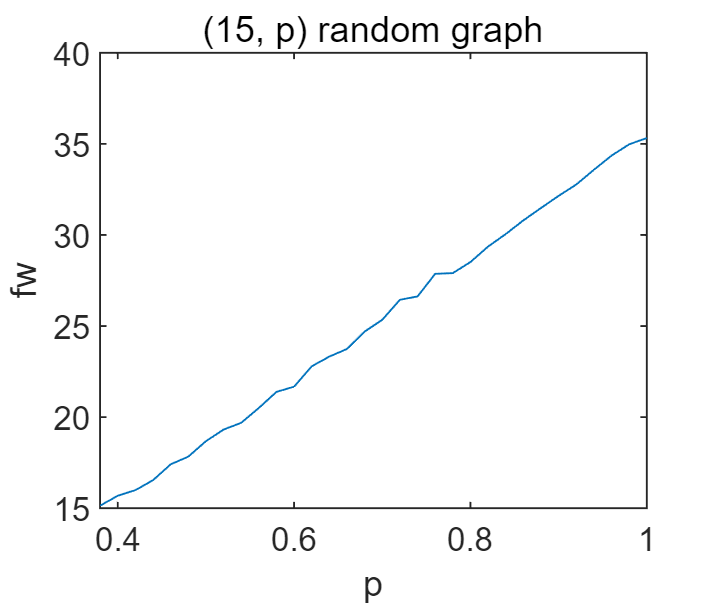

% Calculate 50 values of fw corresponding to 50 probabilities and plot them
p = 0;
for count = 1 : 50
    p = p + 0.02;
    pRecord(count) = p;
    randomGraphs = gen_N_p_random_graphs(size, N, p);
    temp = zeros(1, size);
    for index = 1 : size
        temp(index) = 0.34 * cal_avg_path_len(randomGraphs{index}) + 0.33 * cal_diameter(randomGraphs{index}) + 0.33 * cal_link_num(randomGraphs{index});
    end
    fwRecord(count) = mean(temp);
end

plot(pRecord, fwRecord);
xlabel("p")
ylabel("fw")
title("(" + N + ", p)" + " random graph");